# sub-03

This code begins by importing raw SEEG data and converting to Fieldtrip format. 

It then edit the SEEG channel labels, inspects the SEEG data, and remove any bad channels.

Following this, the code redefines resting, 0-back, 1-back and 2-back blocks using TRIG or Event channel signals.   

## Set working directory

clc;clear;close all;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\fieldtrip-20231220;
ft_defaults;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\iEEGPrep
iEEGPrep_initial;
cd  Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS;
subID = 'sub-03';
cd(fullfile(subID, 'ieeg'));

## Import SEEG data and edit channel labels

% Import SEEG data into matlab using fieldtrip style
iEEGpath =  [subID, '_task-nback_run-1_ieeg.edf'];
cfg = [];
cfg.dataset = iEEGpath;
Data = ft_preprocessing(cfg);

found matching BIDS sidecar 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-03\ieeg\sub-03_electrodes.tsv'
reading 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-03\ieeg\sub-03_electrodes.tsv'


 In ft_read_header at line 2937

processing channel { 'Event' 'ta1' 'ta2' 'ta3' 'ta4' 'ta5' 'ta6' 'ta7' 'ta8' 'ta9' 'ta10' 'ta11' 'ta12' 'th1' 'th2' 'th3' 'th4' 'th5' 'th6' 'th7' 'th8' 'th9' 'th10' 'b'1' 'b'2' 'b'3' 'b'4' 'b'5' 'b'6' 'b'7' 'b'8' 'f1' 'f2' 'f3' 'f4' 'f5' 'f6' 'f7' 'f8' 'b1' 'b2' 'b3' 'b4' 'b5' 'b6' 'b7' 'b8' 'ti1' 'ti2' 'ti3' 'ti4' 'ti5' 'ti6' 'ti7' 'ti8' 'to1' 'to2' 'to3' 'to4' 'to5' 'to6' 'to7' 'to8' 'to9' 'to10' 'to11' 'to12' 'p1' 'p2' 'p3' 'p4' 'p5' 'p6' 'p7' 'p8' 'p9' 'p10' 'p11' 'p12' 'p13' 'p14' 'p15' 'p16' 'p17' 'p18' 'oh'1' 'oh'2' 'oh'3' 'oh'4' 'oh'5' 'oh'6' 'oh'7' 'oh'8' 'oh'9' 'oh'10' 'oh'11' 'oh'12' 'oh'13' 'oh'14' 'oh'15' 'oh'16' 'oh'17' 'oh'18' 'fu'1' 'fu'2' 'fu'3' 'fu'4' 'fu'5' 'fu'6' 'fu'7' 'fu'8' 'fu'9' 'fu'10' 'fu'11' 'fu'12' 'th'1' 'th'2' 'th'3' 'th'4' 'th'5' 'th'6' 'th'7' 'th'8' 'th'9' 'th'10' 'th'11' 'th'12' 'C127' 'C128' 'DC1' 'DC2'

Event = abs(Data.trial{1}(146, :));
fsample = Data.fsample;

## Remove bad channels

% Remove non-iEEG channels
badChan{1} = {};
for i = 127:128; badChan{1}{i-126} = ['-C', num2str(i)]; end
for i = 1:16; badChan{1}{2+i} = ['-DC', num2str(i)]; end
badChan{1} = [badChan{1}, {'-Event', '-TRIG', '-OSAT', '-PR', '-Pleth'}];
cfg = [];
cfg.channel = [{'all'}, badChan{1}];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 2 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 2 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove bad channels
badChan{1} = {'-ta7', '-ta8'};
cfg = [];
cfg.channel = [{'all'}, badChan{1}];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 2 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 2 seconds


Data = rmfield(Data, 'elec');
BPfreq = [1, 120];
DataPrep = f_filter_bandpass(Data, BPfreq);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 24 seconds


RSfreq = 250;
DataPrep = f_filter_resample(DataPrep, RSfreq);

the input is raw data with 124 channels and 1 trials
the call to "ft_selectdata" took 0 seconds
resampling data
resampling data in trial 1 from 1

original sampling rate = 2.047999e+03 Hz
new sampling rate = 2.499998e+02 Hz
the call to "ft_resampledata" took 9 seconds


chanGroups = f_chanGroup(DataPrep.label);
refMethod = 'CommonAverage';
DataPrep = f_reref_SEEG(DataPrep, refMethod, chanGroups);

 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


the input is raw data with 124 channels and 1 trials


detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


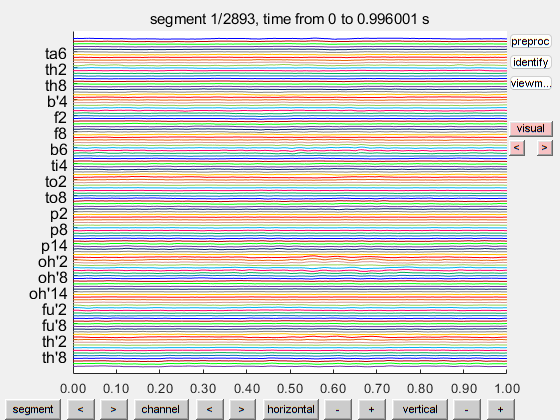

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.viewmode = 'vertical';
ft_databrowser(cfg, DataPrep);

## Redefine the resting blocks

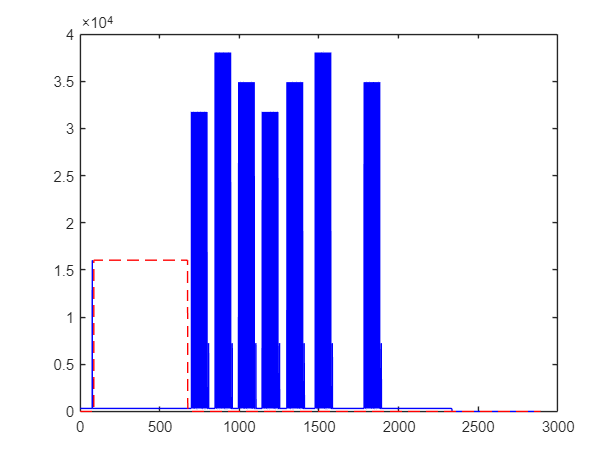

EventValue = unique(Event);
rsValue = EventValue(4);
rsPointer = Event == rsValue;
rsStart = find(diff(rsPointer)==1);
rsStart = rsStart + ceil(10*fsample);
rsEnd = rsStart + ceil(10*60*fsample-10*fsample);
rsPointer = zeros(size(Event));
rsPointer(rsStart:rsEnd) = 1;
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, rsValue*rsPointer, '--r');
hold off;

% Construct data
rsSignals = Data.trial{1}(:, rsStart:rsEnd);
sampleinfo = [1, size(rsSignals, 2)];
rsTime = Data.time{1}(rsStart:rsEnd);
rsData.cfg = Data.cfg;
rsData.fsample = fsample;
rsData.label = Data.label;
rsData.hdr = Data.hdr;
rsData.trial{1} = rsSignals;
rsData.time{1} = rsTime;
rsData.sampleinfo = sampleinfo;
save([subID, '_task-resting_run-1_ieeg.mat'], 'rsData');
disp('***************************************')

***************************************


## Redefine 0-back blocks

% Import SEEG data and convert Fieldtrip format
clc;clear;close all;
subID = 'sub-03';
iEEGpath = [subID, '_task-nback_run-2_ieeg.edf'];
cfg = [];
cfg.dataset = iEEGpath;
Data = ft_preprocessing(cfg);

found matching BIDS sidecar 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-03\ieeg\sub-03_electrodes.tsv'
reading 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-03\ieeg\sub-03_electrodes.tsv'


 In ft_read_header at line 2937

processing channel { 'Event' 'ta1' 'ta2' 'ta3' 'ta4' 'ta5' 'ta6' 'ta7' 'ta8' 'ta9' 'ta10' 'ta11' 'ta12' 'th1' 'th2' 'th3' 'th4' 'th5' 'th6' 'th7' 'th8' 'th9' 'th10' 'b'1' 'b'2' 'b'3' 'b'4' 'b'5' 'b'6' 'b'7' 'b'8' 'f1' 'f2' 'f3' 'f4' 'f5' 'f6' 'f7' 'f8' 'b1' 'b2' 'b3' 'b4' 'b5' 'b6' 'b7' 'b8' 'ti1' 'ti2' 'ti3' 'ti4' 'ti5' 'ti6' 'ti7' 'ti8' 'to1' 'to2' 'to3' 'to4' 'to5' 'to6' 'to7' 'to8' 'to9' 'to10' 'to11' 'to12' 'p1' 'p2' 'p3' 'p4' 'p5' 'p6' 'p7' 'p8' 'p9' 'p10' 'p11' 'p12' 'p13' 'p14' 'p15' 'p16' 'p17' 'p18' 'oh'1' 'oh'2' 'oh'3' 'oh'4' 'oh'5' 'oh'6' 'oh'7' 'oh'8' 'oh'9' 'oh'10' 'oh'11' 'oh'12' 'oh'13' 'oh'14' 'oh'15' 'oh'16' 'oh'17' 'oh'18' 'fu'1' 'fu'2' 'fu'3' 'fu'4' 'fu'5' 'fu'6' 'fu'7' 'fu'8' 'fu'9' 'fu'10' 'fu'11' 'fu'12' 'th'1' 'th'2' 'th'3' 'th'4' 'th'5' 'th'6' 'th'7' 'th'8' 'th'9' 'th'10' 'th'11' 'th'12' 'C127' 'C128' 'DC1' 'DC2'

Event = abs(Data.trial{1}(146, :));
fsample = Data.fsample;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove non-ieeg channels
badChan = {};
for i = 127:128; badChan{i-126} = ['-C', num2str(i)]; end
for i = 1:16; badChan{2+i} = ['-DC', num2str(i)]; end
badChan = [badChan, {'-Event', '-TRIG', '-OSAT', '-PR', '-Pleth'}];
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove bad channels
badChan = {'-ta7', '-ta8'};
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


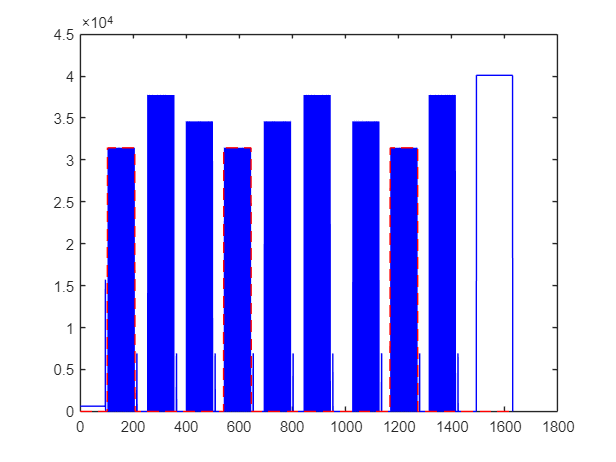

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Redefine 0-back blocks
EventValue = unique(Event);
nb0Value = EventValue(5);
nb0Pointer = Event == nb0Value;
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Pointer = zeros(size(Event));
for nn = 1:length(nb0Start)
    nb0Pointer(nb0Start(nn)-ceil(3*fsample):nb0End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb0Value*nb0Pointer, '--r');
hold off;

% Construct data
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Data.cfg = Data.cfg;
nb0Data.fsample = fsample;
nb0Data.label = Data.label;
nb0Data.hdr = Data.hdr;
for run = 1:3
    sampleinfo = [nb0Start(run), nb0End(run)];
    TRIG{run} = Event(sampleinfo(1):sampleinfo(2));
    nb0Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb0Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb0Data.sampleinfo(run, :) = sampleinfo;
    nb0Data.time{run} = nb0Time;
    nb0Data.trial{run} = nb0Signal;
end
save([subID, '_task-0back_run-1_ieeg.mat'], 'nb0Data','TRIG');
disp('**************************************');

**************************************


## Redefine 1-back blocks

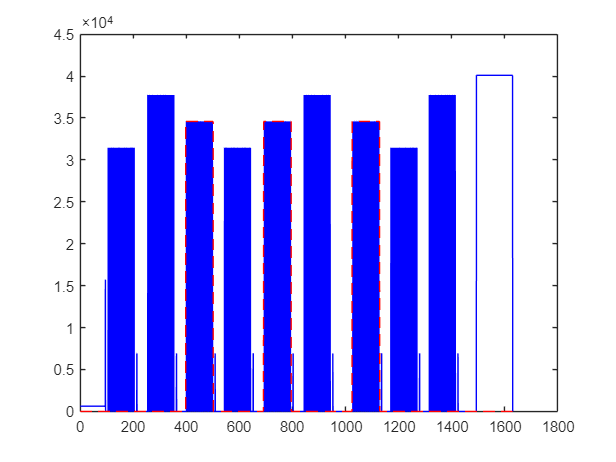

EventValue = unique(Event);
nb1Value = EventValue(6);
nb1Pointer = Event == nb1Value;
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Pointer = zeros(size(Event));
for nn = 1:length(nb1Start)
    nb1Pointer(nb1Start(nn)-ceil(3*fsample):nb1End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb1Value*nb1Pointer, '--r');
hold off;

% Construct data
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Data.cfg = Data.cfg;
nb1Data.fsample = fsample;
nb1Data.label = Data.label;
nb1Data.hdr = Data.hdr;
for run = 1:3
    sampleinfo = [nb1Start(run), nb1End(run)];
    TRIG{run} = Event(sampleinfo(1):sampleinfo(2));
    nb1Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb1Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb1Data.sampleinfo(run, :) = sampleinfo;
    nb1Data.time{run} = nb1Time;
    nb1Data.trial{run} = nb1Signal;
end
save([subID, '_task-1back_run-1_ieeg.mat'], 'nb1Data', 'TRIG');
disp('*****************************');

*****************************


## Redefine 2-back blocks

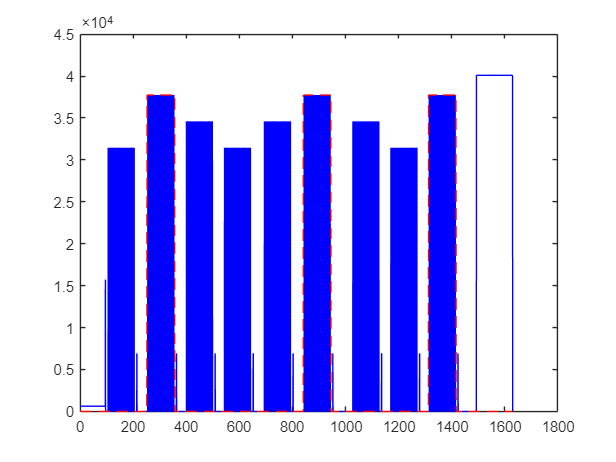

EventValue = unique(Event);
nb2Value = EventValue(7);
nb2Pointer = Event == nb2Value;
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Pointer = zeros(size(Event));
for nn = 1:length(nb2Start)
    nb2Pointer(nb2Start(nn)-ceil(3*fsample):nb2End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb2Value*nb2Pointer, '--r');
hold off;

% Construct data
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Data.cfg = Data.cfg;
nb2Data.fsample = fsample;
nb2Data.label = Data.label;
nb2Data.hdr = Data.hdr;
for run = 1:3
    sampleinfo = [nb2Start(run), nb2End(run)];
    TRIG{run} = Event(sampleinfo(1):sampleinfo(2));
    nb2Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb2Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb2Data.sampleinfo(run, :) = sampleinfo;
    nb2Data.time{run} = nb2Time;
    nb2Data.trial{run} = nb2Signal;
end
save([subID, '_task-2back_run-1_ieeg.mat'], 'nb2Data', 'TRIG');